# Error surfaces

*Bart Krekelberg - Last Update Jan 2023.*

For functions that are linear in their parameters, the error surface only has one global minmum - that makes finding the best solution (i.e. parameters) easy,quick, and guaranteed. For nonlinear parameter dependencies there is no guarantee becuase the error surface has local minima. Some curves/models look nonlinear, but can be made linear with a simple transform: For instance, instead of solving the nonlinear $y ~ a*exp(-bx)$, you should always find solutions after taking the log :$ z = log(y) ~ log(a) - bx.$

Because $y ~ a*exp(-bx)$looks so simple, one might think its error surface only has a single global minimum. This script shows that that intuition is incorrect (and shows how you can calculate and visualize an error surface).

## Simulate data

Simulate a dataset

nrDataPoints = 100;
% Independent variable x
maxX = 1;
minX = -1;
x = minX + (maxX-minX)*rand([nrDataPoints 1]);

% Exponential dependence of y on x
expFun = @(a,b) (a*exp(-b*x));
% Set the true parameters of the exponential
trueA=1;
trueB=2;
% Calculate the true dependent variable Y
trueY = expFun(trueA,trueB);

## Search for a fit

Determine the errors (`sum(residuals.^2)`) by brute force iteration through a range of` a` and `b` around the `trueA` and `trueB`. In real life we would not know these true values, although we might be able to guess them. In practice you don't search for a solution by brute force iteration, but by using a faster/more accurate algorithm implemented in one of Matlab's curve fitting tools. (One of the problems with the brute force search is that you don't know which `stepSize` to use; if it is too large, you could step over the global minimum).

range = 0.25;
stepSize = 0.01;
a = (-range:stepSize:range) + trueA;
b = (-range:stepSize:range) + trueB;
[~,ixTrueA]  = min(abs(a-trueA));
[~,ixTrueB]  = min(abs(b-trueB));
nrA= numel(a);
nrB = numel(b);
E = nan(nrB,nrA);
for i=1:numel(a)
    for j=1:numel(b)
        residual = expFun(a(i),b(j))-trueY;
        E(j,i) = sum(residual.^2);
    end
end

## Visualize

The Energy surface range is really large, making small dips hard to see. We scale it by taking the log (which does not change the shape of the surface, because it is a monotonic function), but have to add `eps` to avoid a NaN for the perfect solution.

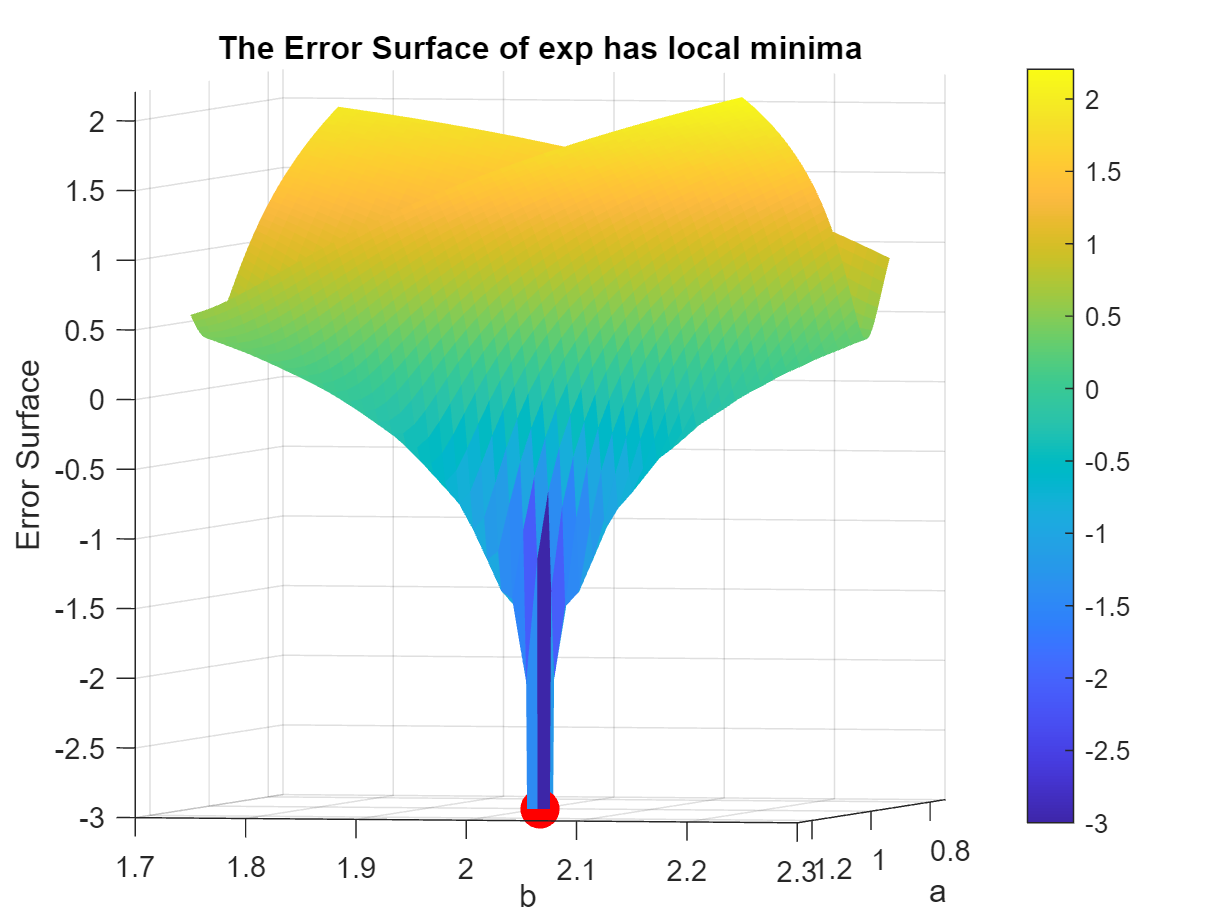

logE = log10(E+eps);
% For visualization I also clamp the lowest value 
minLogE = -3;

clf
surf(a,b,logE)
shading flat
lims = [minLogE max(logE(:))];
set(gca,'ZLim',lims,'CLim',lims)
xlabel 'a'
ylabel 'b'
zlabel 'Error Surface'
hold on
plot3 (trueA,trueB,minLogE,'r.','MarkerSize',40); % Show the perfect solution
colorbar
title 'The Error Surface of exp has local minima'

You can use the mouse to rotate the error surface (hover your mouse over the graph, then click on the circular arrow with a cube in the middle, then click and drag the surface).; the local minima are more obvious from some perspectives than others.